# Cargar datos:

libre = readmatrix('Datos/vibracion_libre.txt');

Función:

function [A1,xi,omega_n,omega_d,T_n] = obtenerModelo(t,y)

% Primeros 3 picos
[pks,locs] = findpeaks(y,t,'MinPeakHeight',4);

primeros_tiempos = locs(1:3);

T1 = primeros_tiempos(2)-primeros_tiempos(1);
T2 = primeros_tiempos(3)-primeros_tiempos(2);

T_n = mean([T1 T2])

% Frecuencia amortiguada
omega_d = 2*pi/T_n

% Amplitudes consecutivas
[A1,idx] = max(y);
Amp_max=A1
tmax = t(idx);

t_objetivo = tmax + T_n;

[~,idx2] = min(abs(t-t_objetivo));

A2 = y(idx2);

% Decremento logarítmico
delta = log(A1/A2)

xi = delta/sqrt(4*pi^2 + delta^2)

% Frecuencia natural
omega_n = omega_d/sqrt(1-xi^2)

end

function x = vibracion(t,A,omega_n,omega_d,xi)

x = A.*exp(-xi.*omega_n.*t).*sin(omega_d.*t);

end

t = libre(:,1);
y = libre(:,3);

[A1,xi,omega_n,omega_d,T_n] = obtenerModelo(t,y);

T_n = 0.5500

omega_d = 11.4240

Amp_max = 12.1008

delta = 0.0873

xi = 0.0139

omega_n = 11.4251


y_modelo = vibracion(t,A1,omega_n,omega_d,xi);

# Ploteo de desplazamiento vs tiempo:

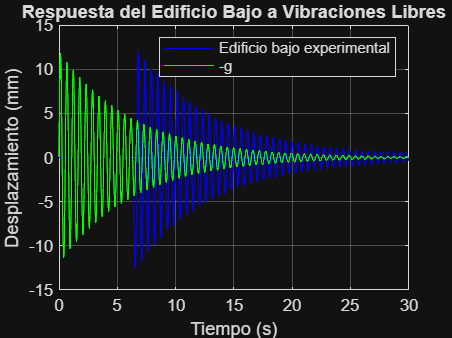

figure
plot(t(1:3000),y(1:3000),'-b')
hold on
plot(t(1:3000),vibracion(t(1:3000),A1,omega_n,omega_d,xi),'-g')
hold off
legend('Edificio bajo teórico','-b')
legend('Edificio bajo experimental','-g')
xlabel('Tiempo (s)')
ylabel('Desplazamiento (mm)')
title('Respuesta del Edificio Bajo a Vibraciones Libres');
grid on;

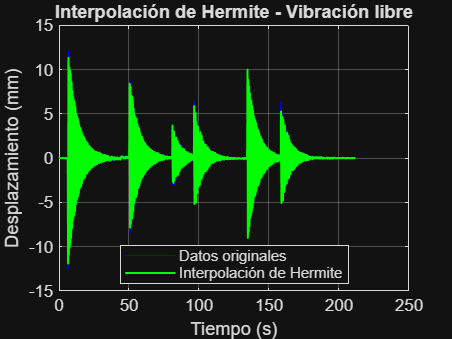

%% Interpolación de Hermite
% Modelado del movimiento de vibración libre mediante interpolación cúbica
% de Hermite construida manualmente (sin usar pchip como solución).
% Compatible con MATLAB Live Script (.mlx).

%% Preparación de datos
% Sustituir por los nombres reales del repositorio si difieren:
%   nombre_archivo    -> 'Datos/vibracion_libre.txt'
%   columna_tiempo    -> 1
%   columna_respuesta -> 3
libre = readmatrix('Datos/vibracion_libre.txt');

t = libre(:,1);   % tiempo (s)
y = libre(:,3);   % desplazamiento (mm)

% Opcional: usar solo el primer tramo, como en el script base del proyecto.
% t = t(1:3000);  y = y(1:3000);

%% Cálculo de derivadas numéricas y evaluación del interpolante
n_puntos = 3000;                                   % resolución de la malla fina
[t_fino, x_hermite, dxdt] = hermite_vibracion(t, y, n_puntos);

%% Gráfica de resultados
figure
plot(t, y, '-b')                                   % datos originales
hold on
plot(t_fino, x_hermite, '-g', 'LineWidth', 1.2)    % interpolación de Hermite
hold off
legend('Datos originales', 'Interpolación de Hermite', 'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Desplazamiento (mm)')
title('Interpolación de Hermite - Vibración libre')
grid on


%% (Opcional) Comparación con pchip
% pchip de MATLAB tambien es Hermite por tramos, pero con derivadas que
% preservan monotonia. Sirve SOLO como referencia, no sustituye el metodo.
% x_pchip = pchip(t, y, t_fino);
% hold on; plot(t_fino, x_pchip, '--r'); 
% legend('Datos originales', 'Hermite (manual)', 'pchip');

%% Funciones auxiliares
function [t_fino, x_hermite, dxdt] = hermite_vibracion(t, x, n_puntos)
% HERMITE_VIBRACION  Interpolacion cubica de Hermite por tramos.
%   [t_fino, x_hermite, dxdt] = hermite_vibracion(t, x, n_puntos)
%   construye el interpolante cubico de Hermite a partir de los datos
%   discretos (t, x) y lo evalua en n_puntos equiespaciados.
%
%   Si la base de datos no contiene derivadas, estas se aproximan con
%   diferencias finitas:
%       - adelante en el primer punto,
%       - atras  en el ultimo punto,
%       - centrada en los puntos interiores.
%
%   Entradas:
%     t        - vector de tiempos
%     x        - vector de respuesta del sistema (desplazamiento, etc.)
%     n_puntos - cantidad de puntos de la malla fina de evaluacion
%
%   Salidas:
%     t_fino    - malla fina de tiempo
%     x_hermite - valores interpolados por Hermite
%     dxdt      - derivadas aproximadas en los nodos

    % --- Asegurar vectores columna ---
    t = t(:);
    x = x(:);

    % --- Ordenar por tiempo ---
    [t, idx] = sort(t);
    x = x(idx);

    % --- Eliminar tiempos repetidos (y advertir) ---
    n_antes = length(t);
    [t, iu] = unique(t);     % t queda ordenado y sin repeticiones
    x = x(iu);
    if length(t) < n_antes
        warning('hermite_vibracion:duplicados', ...
            'Se eliminaron %d valores de tiempo repetidos.', n_antes - length(t));
    end

    n = length(t);
    if n < 2
        error('Se necesitan al menos 2 puntos para interpolar.');
    end

    % --- Derivadas numericas en los nodos (diferencias finitas) ---
    dxdt = zeros(n, 1);
    dxdt(1) = (x(2) - x(1)) / (t(2) - t(1));             % adelante
    dxdt(n) = (x(n) - x(n-1)) / (t(n) - t(n-1));         % atras
    for i = 2:n-1
        dxdt(i) = (x(i+1) - x(i-1)) / (t(i+1) - t(i-1)); % centrada
    end

    % --- Malla fina de evaluacion ---
    t_fino = linspace(t(1), t(n), n_puntos)';
    x_hermite = zeros(size(t_fino));

    % --- Evaluacion del interpolante de Hermite por tramos ---
    for k = 1:n-1
        ti  = t(k);
        ti1 = t(k+1);
        hi  = ti1 - ti;                 % h_i = t_{i+1} - t_i

        % Puntos de la malla que caen en el intervalo [ti, ti1]
        if k < n-1
            sel = find(t_fino >= ti & t_fino <  ti1);
        else
            sel = find(t_fino >= ti & t_fino <= ti1);   % incluye el extremo final
        end

        s = (t_fino(sel) - ti) / hi;    % s = (t - t_i) / h_i

        % Funciones base de Hermite
        h00 =  2*s.^3 - 3*s.^2 + 1;
        h10 =      s.^3 - 2*s.^2 + s;
        h01 = -2*s.^3 + 3*s.^2;
        h11 =      s.^3 -   s.^2;

        % H_i(t) = h00*x_i + h10*h_i*x'_i + h01*x_{i+1} + h11*h_i*x'_{i+1}
        x_hermite(sel) = h00*x(k)   + h10*hi*dxdt(k) ...
                       + h01*x(k+1) + h11*hi*dxdt(k+1);
    end
end

%% Splines cúbicos
% Modelado del movimiento de vibración libre mediante splines cúbicos
% naturales construidos manualmente (sin usar spline/csape/interp1).
% Compatible con MATLAB Live Script (.mlx).

%% Preparación de datos
% Sustituir por los nombres reales del repositorio si difieren:
%   nombre_archivo    -> 'Datos/vibracion_libre.txt'
%   columna_tiempo    -> 1
%   columna_respuesta -> 3
libre = readmatrix('Datos/vibracion_libre.txt');

t = libre(:,1);   % tiempo (s)
y = libre(:,3);   % desplazamiento (mm)

% Opcional: usar solo el primer tramo, como en el script base del proyecto.
% t = t(1:3000);  y = y(1:3000);

%% Construcción del sistema, cálculo de coeficientes y evaluación
n_puntos = 3000;                                   % resolución de la malla fina
[t_fino, x_spline, coeficientes] = spline_cubico_vibracion(t, y, n_puntos);

% Mostrar las primeras filas de la tabla de coeficientes
disp(head(coeficientes, 8));

    i    t_i     t_ip1        a           b           c          d   
    _    ____    _____    _________    ________    _______    _______

    1       0    0.01     -0.009357    -0.63529          0    -213.11
    2    0.01    0.02     -0.015923    -0.69922    -6.3934     7631.6
    3    0.02    0.03     -0.015923      1.4624     222.55     -11891
    4    0.03    0.04      0.009065      2.3461    -134.18       4366
    5    0.04    0.05      0.023474     0.97229    -3.2011    -3292.8
    6    0.05    0.06      0.029584    -0.07957    -101.98     3607.2
    7    0.06    0.07      0.022197     -1.0371     6.2308      15858
    8    0.07    0.08      0.028307      3.8449     481.97     -46247



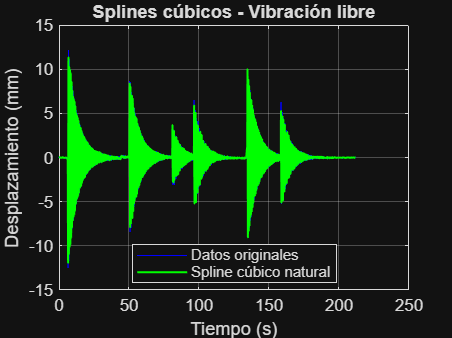


%% Gráfica de resultados
figure
plot(t, y, '-b')                                   % datos originales
hold on
plot(t_fino, x_spline, '-g', 'LineWidth', 1.2)     % interpolación por splines
hold off
legend('Datos originales', 'Spline cúbico natural', 'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Desplazamiento (mm)')
title('Splines cúbicos - Vibración libre')
grid on


%% (Opcional) Comparación con spline de MATLAB
% La funcion spline de MATLAB usa condicion not-a-knot, no natural.
% Sirve SOLO como referencia, no sustituye el metodo construido arriba.
% x_ref = spline(t, y, t_fino);
% hold on; plot(t_fino, x_ref, '--r');
% legend('Datos originales', 'Spline natural (manual)', 'spline (MATLAB)');

%% Funciones auxiliares
function [t_fino, x_spline, coeficientes] = spline_cubico_vibracion(t, x, n_puntos)
% SPLINE_CUBICO_VIBRACION  Spline cubico natural por tramos.
%   [t_fino, x_spline, coeficientes] = spline_cubico_vibracion(t, x, n_puntos)
%   construye el spline cubico natural a partir de los datos discretos
%   (t, x) y lo evalua en n_puntos equiespaciados.
%
%   En cada intervalo [t_i, t_{i+1}]:
%       S_i(t) = a_i + b_i(t-t_i) + c_i(t-t_i)^2 + d_i(t-t_i)^3
%
%   Condiciones de spline natural: S''(t_0) = 0 y S''(t_n) = 0.
%
%   Entradas:
%     t        - vector de tiempos
%     x        - vector de respuesta del sistema (desplazamiento, etc.)
%     n_puntos - cantidad de puntos de la malla fina de evaluacion
%
%   Salidas:
%     t_fino       - malla fina de tiempo
%     x_spline     - valores interpolados por el spline
%     coeficientes - tabla con columnas i, t_i, t_ip1, a, b, c, d

    % --- Asegurar vectores columna ---
    t = t(:);
    x = x(:);

    % --- Ordenar por tiempo ---
    [t, idx] = sort(t);
    x = x(idx);

    % --- Eliminar tiempos repetidos (y advertir) ---
    n_antes = length(t);
    [t, iu] = unique(t);     % t queda ordenado y sin repeticiones
    x = x(iu);
    if length(t) < n_antes
        warning('spline_cubico:duplicados', ...
            'Se eliminaron %d valores de tiempo repetidos.', n_antes - length(t));
    end

    N = length(t);           % numero de nodos
    if N < 3
        error('Se necesitan al menos 3 puntos para un spline cubico.');
    end

    % --- Anchos de los intervalos ---
    h = diff(t);             % h(i) = t(i+1) - t(i),  i = 1..N-1

    % ----------------------------------------------------------------
    % Construccion del sistema tridiagonal para los coeficientes c
    % (c_i = S''(t_i)/2).  Filas 1 y N imponen el spline natural.
    % ----------------------------------------------------------------
    sub  = zeros(N,1);   % subdiagonal  (coef. de c_{i-1})
    diag = zeros(N,1);   % diagonal     (coef. de c_i)
    sup  = zeros(N,1);   % superdiagonal(coef. de c_{i+1})
    d    = zeros(N,1);   % lado derecho

    % Condiciones naturales:  c_1 = 0  y  c_N = 0
    diag(1) = 1;   d(1) = 0;
    diag(N) = 1;   d(N) = 0;

    % Ecuaciones interiores  i = 2..N-1
    for i = 2:N-1
        sub(i)  = h(i-1);
        diag(i) = 2*(h(i-1) + h(i));
        sup(i)  = h(i);
        d(i)    = 3*( (x(i+1)-x(i))/h(i) - (x(i)-x(i-1))/h(i-1) );
    end

    % --- Resolucion del sistema tridiagonal (algoritmo de Thomas) ---
    % Eliminacion hacia adelante
    for i = 2:N
        w       = sub(i)/diag(i-1);
        diag(i) = diag(i) - w*sup(i-1);
        d(i)    = d(i)    - w*d(i-1);
    end
    % Sustitucion hacia atras
    c = zeros(N,1);
    c(N) = d(N)/diag(N);
    for i = N-1:-1:1
        c(i) = (d(i) - sup(i)*c(i+1)) / diag(i);
    end

    % ----------------------------------------------------------------
    % Calculo de coeficientes a, b, d de cada tramo  i = 1..N-1
    % ----------------------------------------------------------------
    a = zeros(N-1,1);
    b = zeros(N-1,1);
    dd = zeros(N-1,1);   % coeficiente d_i (cubico)
    for i = 1:N-1
        a(i)  = x(i);
        b(i)  = (x(i+1)-x(i))/h(i) - h(i)/3*(2*c(i) + c(i+1));
        dd(i) = (c(i+1) - c(i)) / (3*h(i));
    end
    c_tramo = c(1:N-1);   % c_i de cada tramo (el c_N solo cierra el sistema)

    % --- Tabla de coeficientes ---
    coeficientes = table((1:N-1)', t(1:N-1), t(2:N), a, b, c_tramo, dd, ...
        'VariableNames', {'i','t_i','t_ip1','a','b','c','d'});

    % ----------------------------------------------------------------
    % Evaluacion del spline en la malla fina
    % ----------------------------------------------------------------
    t_fino   = linspace(t(1), t(N), n_puntos)';
    x_spline = zeros(size(t_fino));

    for k = 1:N-1
        ti  = t(k);
        ti1 = t(k+1);

        % Puntos de la malla que caen en el intervalo [ti, ti1]
        if k < N-1
            sel = find(t_fino >= ti & t_fino <  ti1);
        else
            sel = find(t_fino >= ti & t_fino <= ti1);   % incluye el extremo final
        end

        dt = t_fino(sel) - ti;   % (t - t_i)
        x_spline(sel) = a(k) + b(k)*dt + c_tramo(k)*dt.^2 + dd(k)*dt.^3;
    end
end

%% Interpolación de Lagrange
% Modelado del movimiento de vibración libre mediante interpolación
% polinómica de Lagrange construida manualmente (sin usar polyfit/interp1).
% Compatible con MATLAB Live Script (.mlx).

%% Preparación de datos
% Sustituir por los nombres reales del repositorio si difieren:
%   nombre_archivo    -> 'Datos/vibracion_libre.txt'
%   columna_tiempo    -> 1
%   columna_respuesta -> 3
libre = readmatrix('Datos/vibracion_libre.txt');

t = libre(:,1);   % tiempo (s)
y = libre(:,3);   % desplazamiento (mm)

% Opcional: trabajar solo con el primer tramo, como en el script base.
% t = t(1:3000);  y = y(1:3000);

%% Selección de nodos y evaluación del interpolante
% IMPORTANTE: el polinomio de Lagrange es UN solo polinomio de grado
% (num_nodos - 1). Si se usan demasiados nodos, el grado crece y aparecen
% oscilaciones grandes cerca de los extremos (fenomeno de Runge) y perdida
% de estabilidad numerica. Por eso se usa un numero REDUCIDO de nodos.
num_nodos = 15;     % cantidad de nodos (grado del polinomio = num_nodos - 1)
n_puntos  = 500;    % resolución de la malla fina

[t_fino, x_lagrange, nodos_t, nodos_x] = lagrange_vibracion(t, y, num_nodos, n_puntos);

% Tabla de nodos seleccionados
nodos = table((1:length(nodos_t))', nodos_t, nodos_x, ...
    'VariableNames', {'i','t_i','x_i'});
disp(nodos);

    i      t_i         x_i   
    __    ______    _________

     1         0    -0.009357
     2     15.14       2.9517
     3     30.28       0.3432
     4     45.43      0.14358
     5     60.57        1.144
     6     75.71       0.2189
     7     90.85      0.20477
     8       106      0.66622
     9    121.14    -0.015923
    10    136.28      -4.2777
    11    151.42     -0.26744
    12    166.56     -0.44016
    13    181.71    -0.031608
    14    196.85     0.011071
    15    211.99     0.006876



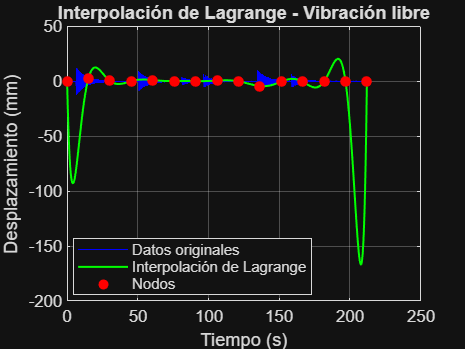


%% Gráfica de resultados
figure
plot(t, y, '-b')                                       % datos originales
hold on
plot(t_fino, x_lagrange, '-g', 'LineWidth', 1.2)       % interpolación Lagrange
scatter(nodos_t, nodos_x, 40, 'r', 'filled')           % nodos seleccionados
hold off
legend('Datos originales', 'Interpolación de Lagrange', 'Nodos', ...
       'Location', 'best')
xlabel('Tiempo (s)')
ylabel('Desplazamiento (mm)')
title('Interpolación de Lagrange - Vibración libre')
grid on


%% (Opcional) Comparación con polyfit/polyval
% polyfit ajusta el mismo polinomio por minimos cuadrados/Vandermonde.
% Sirve SOLO como referencia, no sustituye el metodo construido arriba.
% p = polyfit(nodos_t, nodos_x, length(nodos_t)-1);
% x_ref = polyval(p, t_fino);
% hold on; plot(t_fino, x_ref, '--k');
% legend('Datos','Lagrange (manual)','Nodos','polyfit');

%% Funciones auxiliares
function [t_fino, x_lagrange, nodos_t, nodos_x] = lagrange_vibracion(t, x, num_nodos, n_puntos)
% LAGRANGE_VIBRACION  Interpolacion polinomica de Lagrange (manual).
%   [t_fino, x_lagrange, nodos_t, nodos_x] = ...
%       lagrange_vibracion(t, x, num_nodos, n_puntos)
%   selecciona num_nodos nodos equiespaciados de los datos (t, x),
%   construye el polinomio interpolante de Lagrange y lo evalua en
%   n_puntos equiespaciados.
%
%   P_n(t) = sum_i x_i * L_i(t),  con  L_i(t) = prod_{j~=i} (t-t_j)/(t_i-t_j)
%
%   Entradas:
%     t         - vector de tiempos
%     x         - vector de respuesta del sistema (desplazamiento, etc.)
%     num_nodos - cantidad de nodos a usar (grado = num_nodos - 1)
%     n_puntos  - cantidad de puntos de la malla fina de evaluacion
%
%   Salidas:
%     t_fino     - malla fina de tiempo (entre el primer y ultimo nodo)
%     x_lagrange - valores interpolados por Lagrange
%     nodos_t    - tiempos de los nodos usados
%     nodos_x    - respuesta en los nodos usados

    % --- Asegurar vectores columna ---
    t = t(:);
    x = x(:);

    % --- Ordenar por tiempo ---
    [t, idx] = sort(t);
    x = x(idx);

    % --- Eliminar tiempos repetidos (y advertir) ---
    n_antes = length(t);
    [t, iu] = unique(t);     % t queda ordenado y sin repeticiones
    x = x(iu);
    if length(t) < n_antes
        warning('lagrange_vibracion:duplicados', ...
            'Se eliminaron %d valores de tiempo repetidos.', n_antes - length(t));
    end

    N = length(t);

    % ----------------------------------------------------------------
    % Seleccion de nodos
    %   - Si hay pocos datos, se usan todos.
    %   - Si hay muchos, se toman num_nodos nodos equiespaciados.
    % ----------------------------------------------------------------
    if num_nodos < 2
        num_nodos = 2;
    end
    if N <= num_nodos
        sel = (1:N)';                                  % usar todos los datos
    else
        sel = unique(round(linspace(1, N, num_nodos)))'; % equiespaciados
    end

    nodos_t = t(sel);
    nodos_x = x(sel);
    n = length(nodos_t);     % numero real de nodos (grado = n - 1)

    % Aviso de estabilidad: grados altos -> oscilaciones (Runge)
    if n > 15
        warning('lagrange_vibracion:grado_alto', ...
            ['Se usan %d nodos (grado %d). Grados altos pueden causar ', ...
             'oscilaciones y perdida de estabilidad numerica.'], n, n-1);
    end

    % --- Malla fina (dentro del rango de los nodos) ---
    t_fino = linspace(nodos_t(1), nodos_t(n), n_puntos)';
    x_lagrange = zeros(size(t_fino));

    % ----------------------------------------------------------------
    % Construccion y evaluacion del polinomio de Lagrange
    %   Para cada nodo i se construye L_i(t_fino) como producto y se
    %   acumula x_i * L_i(t_fino).
    % ----------------------------------------------------------------
    for i = 1:n
        Li = ones(size(t_fino));     % L_i(t) inicia en 1
        for j = 1:n
            if j ~= i
                Li = Li .* (t_fino - nodos_t(j)) / (nodos_t(i) - nodos_t(j));
            end
        end
        x_lagrange = x_lagrange + nodos_x(i) * Li;
    end
end

%% Comparación de eficacia de los métodos
% Evalúa Lagrange, splines cúbicos y Hermite en los MISMOS puntos (los
% tiempos originales t) y los compara contra los datos medidos x.
% Para una comparación justa, los tres métodos se construyen con el MISMO
% conjunto de nodos y se evalúan en el mismo vector de tiempo.
%
% Requiere que ya estén cargados:  t  (tiempo)  y  y  (respuesta medida).
%   libre = readmatrix('Datos/vibracion_libre.txt');
%   t = libre(:,1);  y = libre(:,3);

% --- Puntos comunes de comparación ---
t_eval = t;        % comparar en los tiempos originales
x_real = y;        % datos de referencia (medidos)

% --- Nodos comunes para los tres métodos ---
% num_nodos controla el grado del polinomio de Lagrange (grado = num_nodos-1)
% y la cantidad de tramos de spline/Hermite. Subirlo mejora spline/Hermite
% pero degrada Lagrange (oscilaciones de Runge).
num_nodos = 15;
N = length(t);
if N <= num_nodos
    sel_nodos = (1:N)';
else
    sel_nodos = unique(round(linspace(1, N, num_nodos)))';
end
nodos_t = t(sel_nodos);
nodos_x = y(sel_nodos);

% --- Evaluación de cada método en t_eval (con medición de tiempo) ---
tic;
x_lagrange_eval = lagrange_eval(nodos_t, nodos_x, t_eval);
tiempo_lagrange = toc;
% % Si Lagrange proviene de otra implementación, insertar aquí x_lagrange_eval
% % evaluado en t_eval (mismos puntos que x_real).

tic;
x_spline_eval = spline_eval(nodos_t, nodos_x, t_eval);
tiempo_spline = toc;
% % Insertar aquí x_spline_eval evaluado en t_eval si viene de otra parte.

tic;
x_hermite_eval = hermite_eval(nodos_t, nodos_x, t_eval);
tiempo_hermite = toc;
% % Insertar aquí x_hermite_eval evaluado en t_eval si viene de otra parte.

% --- Cálculo de métricas ---
m_lagrange = calcular_metricas(x_real, x_lagrange_eval, tiempo_lagrange);
m_spline   = calcular_metricas(x_real, x_spline_eval,   tiempo_spline);
m_hermite  = calcular_metricas(x_real, x_hermite_eval,  tiempo_hermite);

M = [m_lagrange; m_spline; m_hermite];
Metodo          = ["Lagrange"; "Splines cubicos"; "Hermite"];
MAE             = M(:,1);
RMSE            = M(:,2);
ErrorMaximo     = M(:,3);
R2              = M(:,4);
TiempoEjecucion = M(:,5);

% --- Tabla comparativa ---
tabla_eficacia = table(Metodo, MAE, RMSE, ErrorMaximo, R2, TiempoEjecucion);
disp(tabla_eficacia);

         Metodo           MAE       RMSE     ErrorMaximo       R2       TiempoEjecucion
    _________________    ______    ______    ___________    ________    _______________

    "Lagrange"           13.049    33.477      166.88        -343.73        0.00842    
    "Splines cubicos"    1.2797    2.2835      14.332       -0.60401       0.010803    
    "Hermite"            1.2366    2.2543      14.189       -0.56315       0.011669    




% --- Selección automática del mejor método por RMSE ---
[~, idx_mejor] = min(RMSE);
fprintf('\nEl metodo con menor RMSE es: %s\n', Metodo(idx_mejor));


El metodo con menor RMSE es: Hermite


fprintf(['Un menor RMSE indica mejor ajuste numerico respecto a los datos ', ...
    'evaluados, pero la seleccion final debe considerar tambien la suavidad, ', ...
    'la estabilidad numerica y el comportamiento fisico de la curva.\n']);

Un menor RMSE indica mejor ajuste numerico respecto a los datos evaluados, pero la seleccion final debe considerar tambien la suavidad, la estabilidad numerica y el comportamiento fisico de la curva.


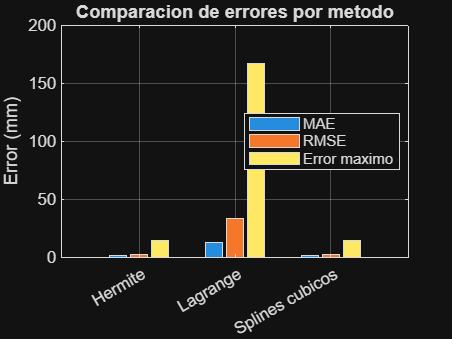


% --- Gráfica opcional de comparación de errores ---
figure
bar(categorical(Metodo), [MAE, RMSE, ErrorMaximo]);
legend('MAE', 'RMSE', 'Error maximo', 'Location', 'best');
ylabel('Error (mm)');
title('Comparacion de errores por metodo');
grid on


%% Funciones auxiliares (comparación)
function metricas = calcular_metricas(x_real, x_estimado, tiempo_ejecucion)
% CALCULAR_METRICAS  Devuelve [MAE, RMSE, ErrorMaximo, R2, tiempo].
    x_real     = x_real(:);
    x_estimado = x_estimado(:);
    err = x_real - x_estimado;

    MAE         = mean(abs(err));
    RMSE        = sqrt(mean(err.^2));
    ErrorMaximo = max(abs(err));

    SS_res = sum(err.^2);
    SS_tot = sum((x_real - mean(x_real)).^2);
    if SS_tot == 0
        R2 = NaN;            % evitar division entre cero
    else
        R2 = 1 - SS_res/SS_tot;
    end

    metricas = [MAE, RMSE, ErrorMaximo, R2, tiempo_ejecucion];
end

function x_eval = lagrange_eval(nodos_t, nodos_x, t_eval)
% LAGRANGE_EVAL  Polinomio de Lagrange (manual) evaluado en t_eval.
    nodos_t = nodos_t(:); nodos_x = nodos_x(:); t_eval = t_eval(:);
    n = length(nodos_t);
    x_eval = zeros(size(t_eval));
    for i = 1:n
        Li = ones(size(t_eval));
        for j = 1:n
            if j ~= i
                Li = Li .* (t_eval - nodos_t(j)) / (nodos_t(i) - nodos_t(j));
            end
        end
        x_eval = x_eval + nodos_x(i) * Li;
    end
end

function x_eval = spline_eval(nodos_t, nodos_x, t_eval)
% SPLINE_EVAL  Spline cubico natural (manual) evaluado en t_eval.
    nt = nodos_t(:); nx = nodos_x(:); t_eval = t_eval(:);
    N = length(nt);
    h = diff(nt);

    % Sistema tridiagonal para c (condiciones naturales c_1 = c_N = 0)
    sub = zeros(N,1); dg = zeros(N,1); sup = zeros(N,1); rhs = zeros(N,1);
    dg(1) = 1; dg(N) = 1;
    for i = 2:N-1
        sub(i) = h(i-1);
        dg(i)  = 2*(h(i-1) + h(i));
        sup(i) = h(i);
        rhs(i) = 3*( (nx(i+1)-nx(i))/h(i) - (nx(i)-nx(i-1))/h(i-1) );
    end
    % Thomas
    for i = 2:N
        w = sub(i)/dg(i-1);
        dg(i)  = dg(i)  - w*sup(i-1);
        rhs(i) = rhs(i) - w*rhs(i-1);
    end
    c = zeros(N,1);
    c(N) = rhs(N)/dg(N);
    for i = N-1:-1:1
        c(i) = (rhs(i) - sup(i)*c(i+1)) / dg(i);
    end

    % Coeficientes por tramo
    a = nx(1:N-1);
    b = zeros(N-1,1); dcoef = zeros(N-1,1);
    for i = 1:N-1
        b(i)     = (nx(i+1)-nx(i))/h(i) - h(i)/3*(2*c(i) + c(i+1));
        dcoef(i) = (c(i+1) - c(i)) / (3*h(i));
    end

    % Evaluacion
    x_eval = zeros(size(t_eval));
    for k = 1:N-1
        ti = nt(k); ti1 = nt(k+1);
        if k < N-1
            sel = find(t_eval >= ti & t_eval <  ti1);
        else
            sel = find(t_eval >= ti & t_eval <= ti1);
        end
        dt = t_eval(sel) - ti;
        x_eval(sel) = a(k) + b(k)*dt + c(k)*dt.^2 + dcoef(k)*dt.^3;
    end
end

function x_eval = hermite_eval(nodos_t, nodos_x, t_eval)
% HERMITE_EVAL  Hermite cubico por tramos (manual) evaluado en t_eval.
    nt = nodos_t(:); nx = nodos_x(:); t_eval = t_eval(:);
    n = length(nt);

    % Derivadas por diferencias finitas en los nodos
    d = zeros(n,1);
    d(1) = (nx(2)-nx(1))/(nt(2)-nt(1));
    d(n) = (nx(n)-nx(n-1))/(nt(n)-nt(n-1));
    for i = 2:n-1
        d(i) = (nx(i+1)-nx(i-1))/(nt(i+1)-nt(i-1));
    end

    % Evaluacion por tramos
    x_eval = zeros(size(t_eval));
    for k = 1:n-1
        ti = nt(k); ti1 = nt(k+1); hi = ti1 - ti;
        if k < n-1
            sel = find(t_eval >= ti & t_eval <  ti1);
        else
            sel = find(t_eval >= ti & t_eval <= ti1);
        end
        s = (t_eval(sel) - ti) / hi;
        h00 =  2*s.^3 - 3*s.^2 + 1;
        h10 =      s.^3 - 2*s.^2 + s;
        h01 = -2*s.^3 + 3*s.^2;
        h11 =      s.^3 -   s.^2;
        x_eval(sel) = h00*nx(k) + h10*hi*d(k) + h01*nx(k+1) + h11*hi*d(k+1);
    end
end